N = 9;  % 无人机数量（不包括中心无人机）
dt = 0.1;  % 时间步长
prediction_horizon = 20;  % 预测时域长度
lambda_r = 0.1;  % 径向控制输入权重
lambda_theta = 0.1;  % 角度控制输入权重
max_iter = 100;  % 最大迭代次数
hold on
% 初始位置（极坐标）
positions = [
    100, 0;
     98, 40.10;
    112, 80.21;
    105, 119.75;
     98, 159.86;
    112, 199.96;
    105, 240.07;
     98, 280.17;
    112, 320.28
];
scatter(positions(:,1).*cosd(positions(:,2)),positions(:,1).*sind(positions(:,2)));
xlabel("x");
ylabel("y")
% 理想位置
ideal_theta = linspace(0, 320, N);  % 理想角度位置
ideal_radius = 100;  % 理想半径

% 系统模型
A = eye(2);
B = eye(2) * dt;

% 目标函数
objective = @(u, r, theta, r_ideal, theta_ideal) ...
    sum(arrayfun(@(k) (r + u(2*k-1) * dt - r_ideal)^2 + ...
    (theta + u(2*k) * dt - theta_ideal)^2 + ...
    lambda_r * u(2*k-1)^2 + lambda_theta * u(2*k)^2, 1:prediction_horizon))

objective = 包含以下值的 function_handle :
    @(u,r,theta,r_ideal,theta_ideal)sum(arrayfun(@(k)(r+u(2*k-1)*dt-r_ideal)^2+(theta+u(2*k)*dt-theta_ideal)^2+lambda_r*u(2*k-1)^2+lambda_theta*u(2*k)^2,1:prediction_horizon))


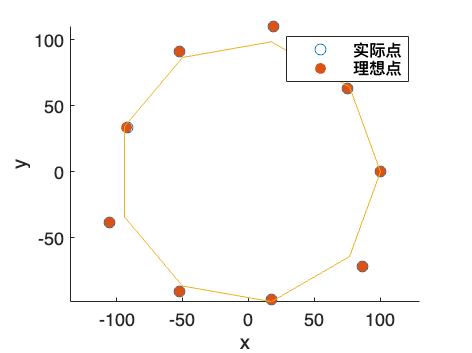

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      41    0.000000e+00    0.000e+00    1.093e-09

初始点是满足约束的局部最小值。

优化已完成，因为在初始点处，目标函数沿可行方向在最优性容差值范围内呈现非递减，并且在约束容差值范围内满足约束。

<停止条件详细信息>
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      41    8.020000e+01    0.000e+00    2.667e-01
    1     

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      41    0.000000e+00    0.000e+00    1.093e-09

初始点是满足约束的局部最小值。

优化已完成，因为在初始点处，目标函数沿可行方向在最优性容差值范围内呈现非递减，并且在约束容差值范围内满足约束。

<停止条件详细信息>
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      41    7.236531e+01    0.000e+00    2.533e-01
    1     


% 约束条件
lb = -ones(2 * prediction_horizon, 1);
ub = ones(2 * prediction_horizon, 1);

% MPC控制
for t = 1:max_iter
    for i = 1:N
        u0 = zeros(2 * prediction_horizon, 1);
        options = optimoptions('fmincon', 'Display', 'iter');
        u_opt = fmincon(@(u) objective(u, positions(i, 1), positions(i, 2), ...
            ideal_radius, ideal_theta(i)), u0, [], [], [], [], lb, ub, [], options);

        % 应用控制输入
        positions(i, 1) = positions(i, 1) + u_opt(1) * dt;
        positions(i, 2) = positions(i, 2) + u_opt(2) * dt;
    end

    % 打印当前时刻的位置
    % fprintf('时间步 %d，位置：\n', t);
    % disp(positions);
    % [rrrm,tttm] = four_a2a3toR()
    plotIteration(positions, ideal_radius)
end


% 输出最终位置
disp('最终位置：');

最终位置：


disp(positions);

  100.0000         0
   99.9998   40.0000
  102.0000   80.0000
  100.0033  120.0000
   99.9998  160.0000
  102.0000  200.0000
  100.0033  240.0000
   99.9998  280.0000
  102.0000  320.0000



hold on
r = positions(:,1);
theta = positions(:,2);
axis equal
x0 = r.*cosd(theta);
y0 = r.*sind(theta);
scatter(x0,y0,'filled');

R = 100;
theta_ideal = 0:2*pi/9:9;
x_ideal = R*cos(theta_ideal);
y_ideal = R*sin(theta_ideal);
plot(x_ideal,y_ideal)


xlabel("x");
ylabel("y")
legend(["初始点","实际点","理想点"])

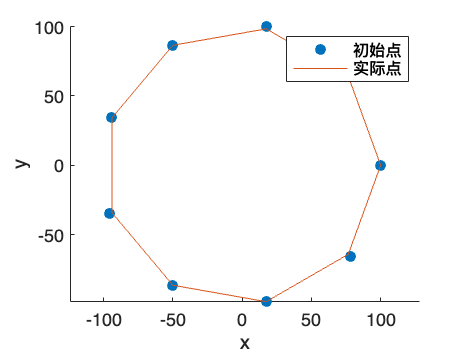




function plotIteration(positions, R)
    % 持续绘图模式
    hold on;
    
    % 提取实际位置的r和theta值
    r = positions(:,1);
    theta = positions(:,2);
    
    % 设置坐标轴比例相等
    axis equal;
    
    % 计算并绘制实际位置的散点图
    x0 = r.*cosd(theta);
    y0 = r.*sind(theta);
    scatter(x0, y0, 'filled');
    
    % 计算并绘制理想位置的圆形轨迹
    theta_ideal = 0:2*pi/9:2*pi; % 修正了结束点，确保完整的圆
    x_ideal = R*cos(theta_ideal);
    y_ideal = R*sin(theta_ideal);
    plot(x_ideal, y_ideal);
    
    % 添加图例和坐标轴标签
    xlabel("x");
    ylabel("y");
    legend(["实际点", "理想点"]);
    
    % 暂停一下以便观察图形，调整暂停时间以适应需求
    pause(0.5);
    
    % 在下一次迭代前清除当前图形，以便重新绘制
    hold off;
    clf;
end

% d = sum_distance(positions(:,1)',deg2rad(positions(:,2)'));
% ss = SS(positions(:,1),positions(:,2))
% tt = sst(positions(:,1),positions(:,2))
% R2 = 1 - ss/tt
hold off

rid_r = positions(:,1)-ideal_radius

rid_r =          0
   -0.0002
    2.0000
    0.0033
   -0.0002
    2.0000
    0.0033
   -0.0002
    2.0000


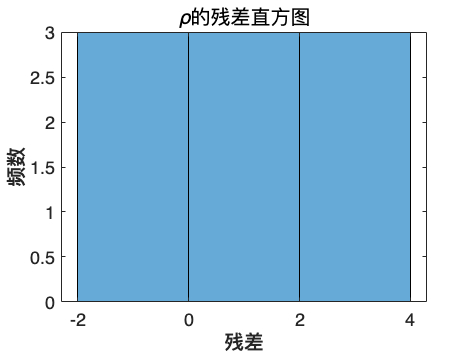

histogram(rid_r);
title('\rho的残差直方图');
xlabel('残差');
ylabel('频数');

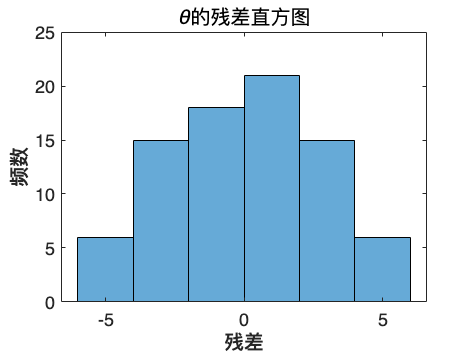

rid_t = deg2rad(positions(:,2) - ideal_theta);
histogram(rid_t);
title('\theta的残差直方图');
xlabel('残差');
ylabel('频数');

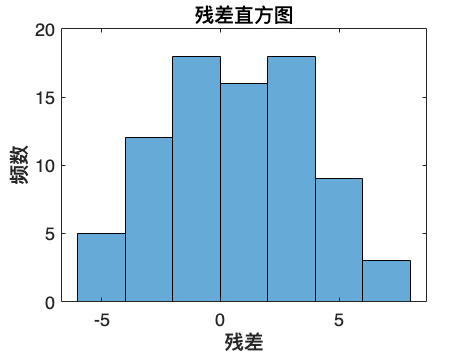

histogram(rid_t+rid_r);
title('残差直方图');
xlabel('残差');
ylabel('频数');